usefull_enthalpy = 2.0833e+05

T_3 = 1000

efficiency = 7.7380e-04

thrust_stat = 211.3913

Q_dot_comb = 2.7319e+05

eff_unitless = 0.3432

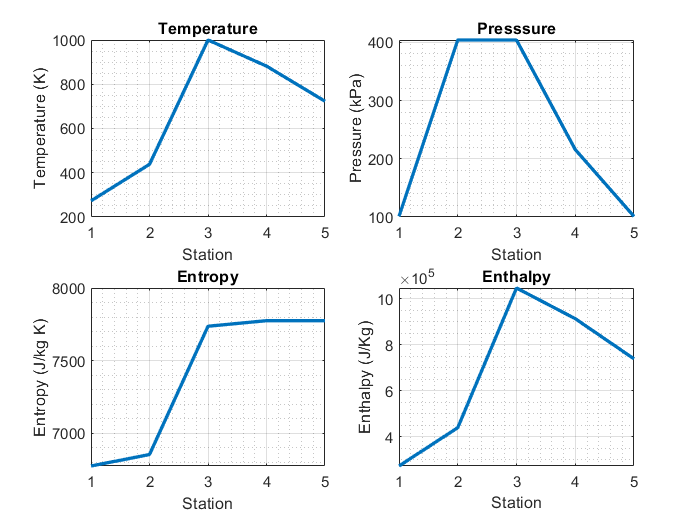

global fluid mass_flow_rate
fluid = 'air.mix';
mass_flow_rate = 0.45;
[thrust_stat, q_dot_tot, h_jump_usable, efficiency] = turbo_jet(273, 101, 1000, 4);

usefull_enthalpy = 9.3859e+04

T_3 = 700

efficiency = 6.0882e-04

thrust_stat = 100.1657

Q_dot_comb = 1.6453e+05

eff_unitless = 0.2567

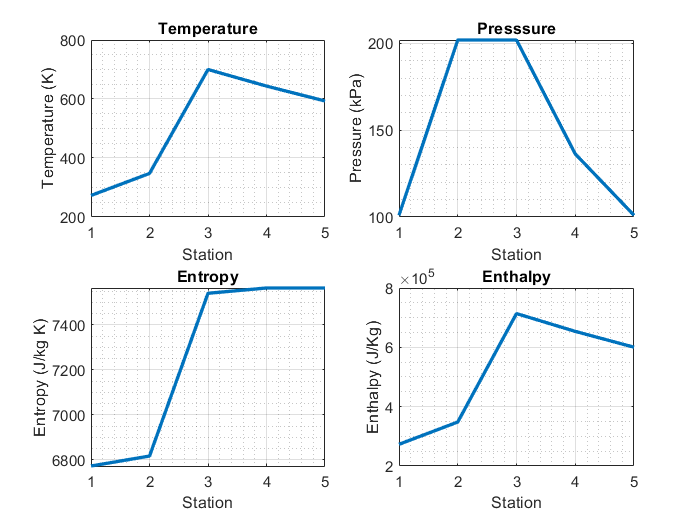

usefull_enthalpy = 9.3859e+04

T_3 = 950

efficiency = 4.7226e-04

thrust_stat = 136.3727

Q_dot_comb = 2.8877e+05

eff_unitless = 0.1463

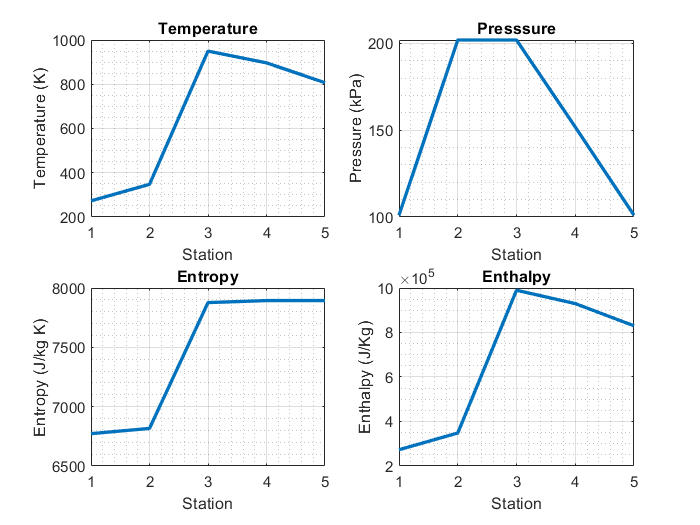

usefull_enthalpy = 9.3859e+04

T_3 = 1200

efficiency = 3.8454e-04

thrust_stat = 160.9808

Q_dot_comb = 4.1863e+05

eff_unitless = 0.1009

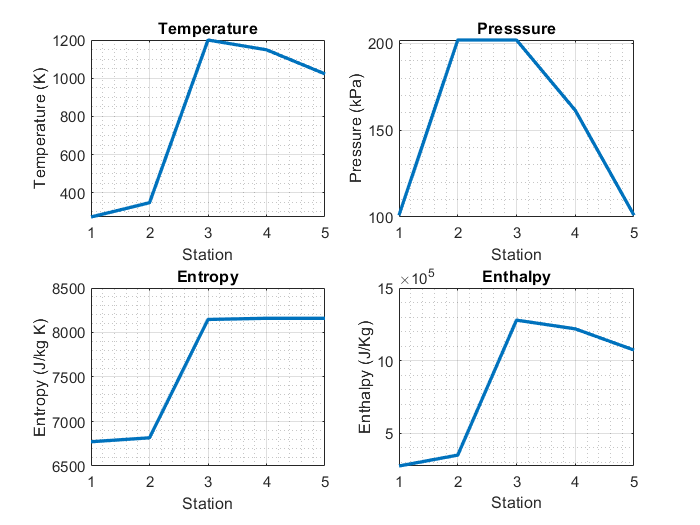

usefull_enthalpy = 1.5805e+05

T_3 = 700

efficiency = 8.7384e-04

thrust_stat = 123.5812

Q_dot_comb = 1.4142e+05

eff_unitless = 0.5029

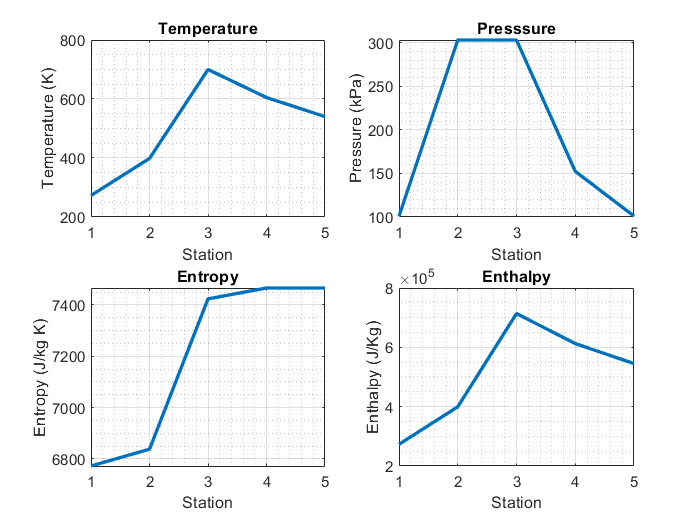

usefull_enthalpy = 1.5805e+05

T_3 = 950

efficiency = 6.7669e-04

thrust_stat = 179.7868

Q_dot_comb = 2.6568e+05

eff_unitless = 0.2677

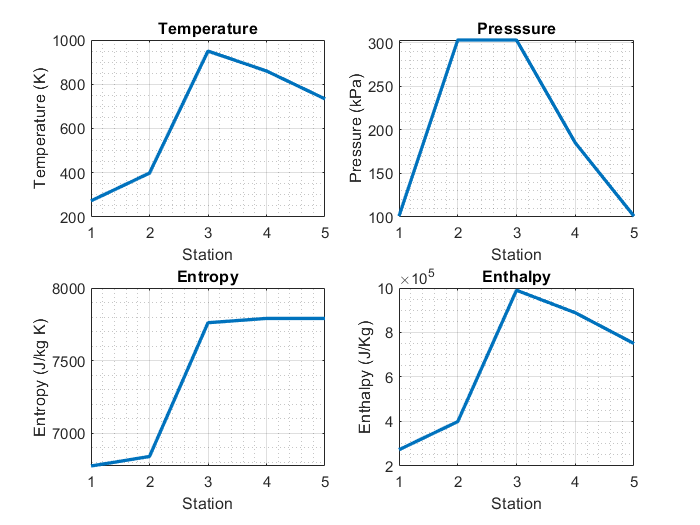

usefull_enthalpy = 1.5805e+05

T_3 = 1200

efficiency = 5.5121e-04

thrust_stat = 218.0336

Q_dot_comb = 3.9556e+05

eff_unitless = 0.1798

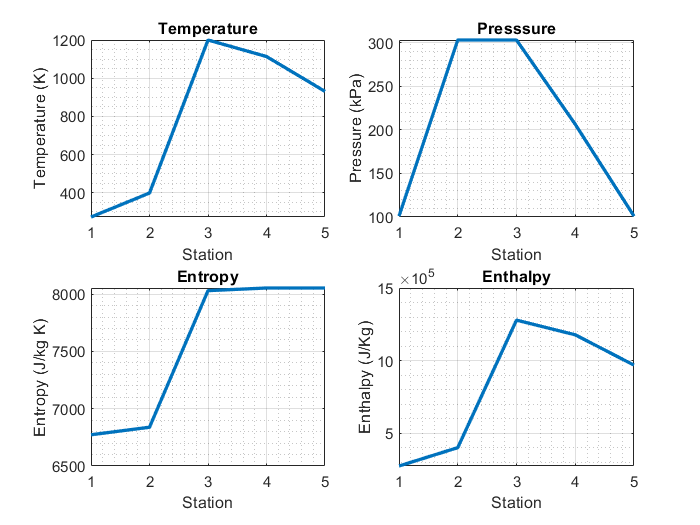

usefull_enthalpy = 2.0833e+05

T_3 = 700

efficiency = 0.0011

thrust_stat = 129.6836

Q_dot_comb = 1.2333e+05

eff_unitless = 0.7601

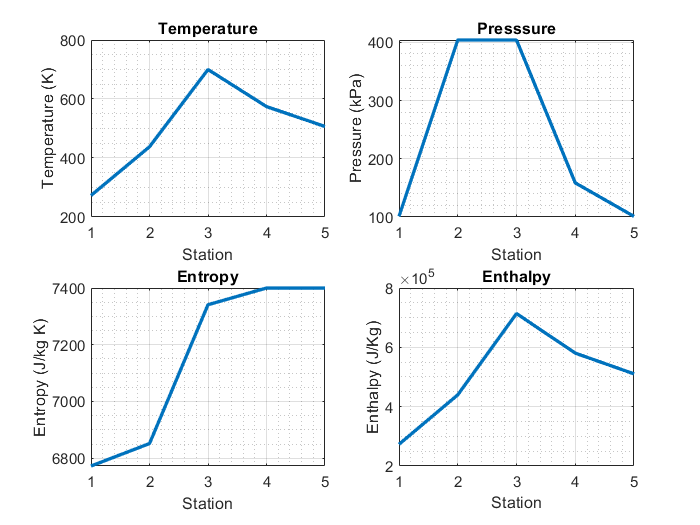

usefull_enthalpy = 2.0833e+05

T_3 = 950

efficiency = 8.1049e-04

thrust_stat = 200.6840

Q_dot_comb = 2.4761e+05

eff_unitless = 0.3786

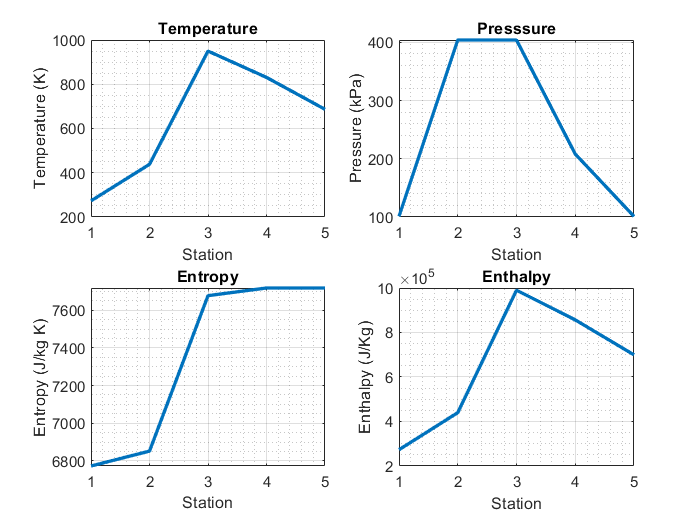

usefull_enthalpy = 2.0833e+05

T_3 = 1200

efficiency = 6.5714e-04

thrust_stat = 248.0667

Q_dot_comb = 3.7749e+05

eff_unitless = 0.2483

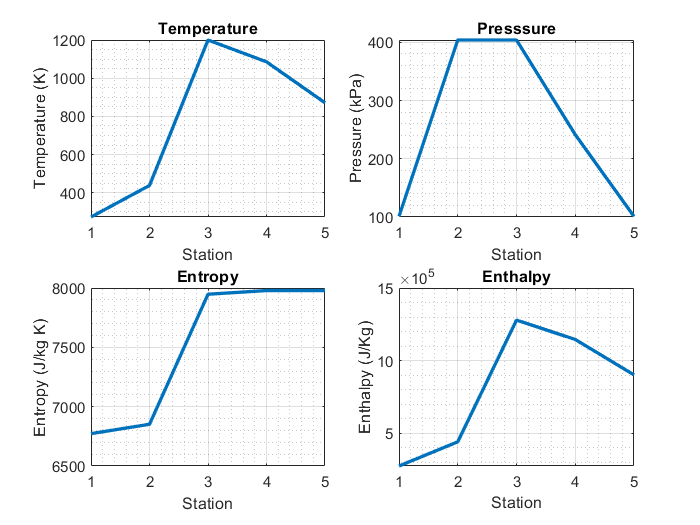

usefull_enthalpy = 2.5027e+05

T_3 = 700

efficiency = 0.0012

thrust_stat = 128.4569

Q_dot_comb = 1.0824e+05

eff_unitless = 1.0405

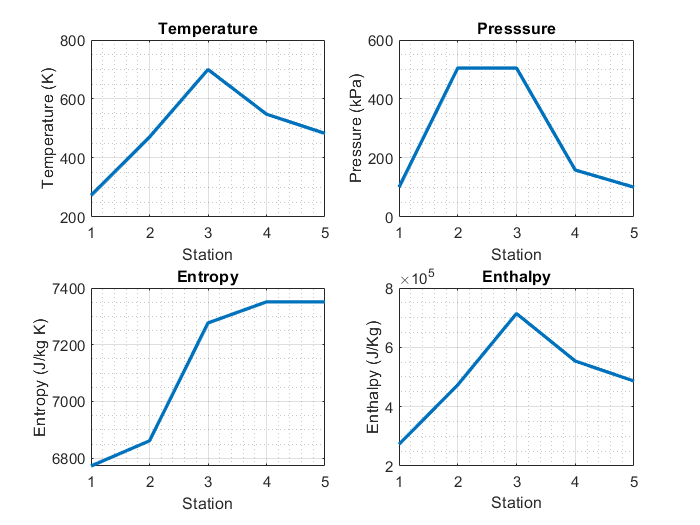

usefull_enthalpy = 2.5027e+05

T_3 = 950

efficiency = 9.1193e-04

thrust_stat = 212.0538

Q_dot_comb = 2.3253e+05

eff_unitless = 0.4843

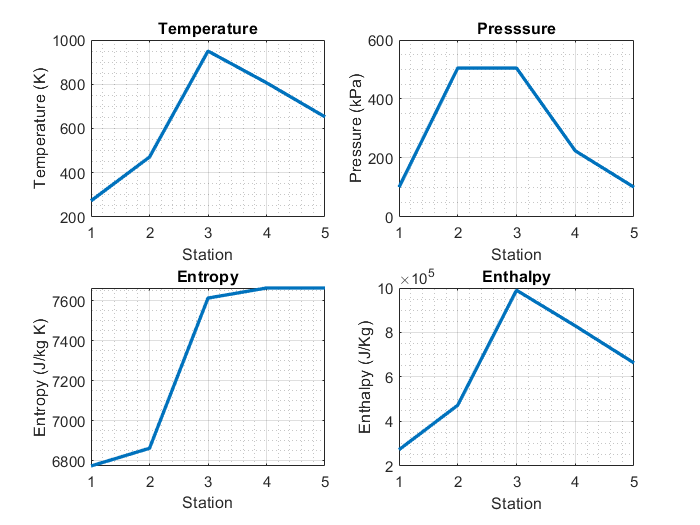

usefull_enthalpy = 2.5027e+05

T_3 = 1200

efficiency = 7.3518e-04

thrust_stat = 266.4475

Q_dot_comb = 3.6243e+05

eff_unitless = 0.3107

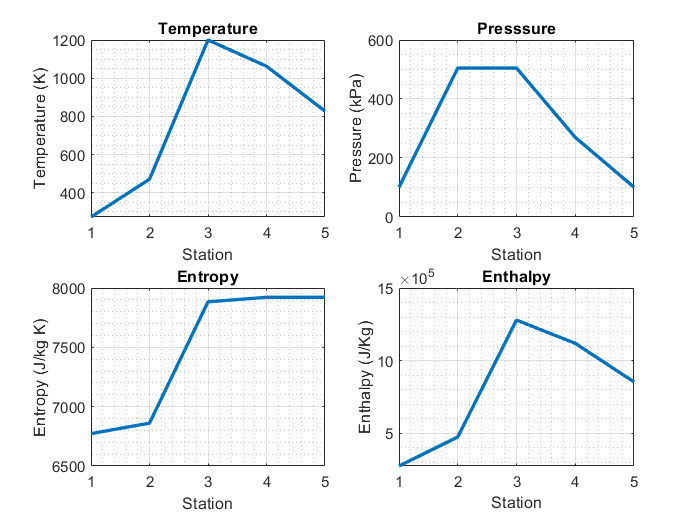





T_hot = linspace(700, 1200, 3);
P_ratio = linspace(2, 5, 4);
clear data;

for i=1:length(P_ratio)
    for j=1:length(T_hot)
        [thrust_stat, q_dot_tot, h_jump_usable, efficiency] = turbo_jet(273, 101, T_hot(j), P_ratio(i));
        data(i, j) = efficiency;
    end
end

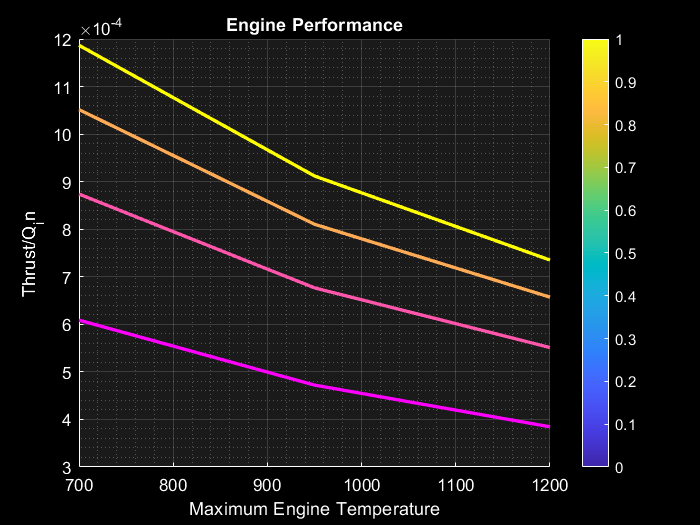

figure(1)
clf
hold on
cmap = spring(length(P_ratio));

for i=1:length(P_ratio)
    plot(T_hot, data(i,:), "LineWidth", 2, "Color", cmap(i,:))
end

 set(gca,'Color', [0.1 0.1 0.1])
    set(gca,'XColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
    set(gca,'ZColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
    set(gcf,'Color','k')
    set(gcf, 'InvertHardcopy', 'off');
print(gcf,'plot.png','-dpng','-r600')

c = colorbar;
c.Color = [1 1 1];
grid on
grid minor
title("Engine Performance", "color", [1 1 1])
ylabel("Thrust/Q_in")
xlabel("Maximum Engine Temperature")



n_united = thrust_stat / q_dot_tot %efficiency in N/W

n_united = 7.3518e-04

n_unitless = mass_flow_rate * h_jump_usable/q_dot_tot %unitless efficiency

n_unitless = 0.3107